# LAB 3: STEP RESPONSE IDENTIFICATION OF DC MOTOR

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Seyed Yazdan Zinati';
Students.ID = '260928077';
%---------------------------------------

## **0. Objectives**

In this lab, we will identify the transfer function of the Virtual DC Motor. We will use `MATLAB` to interact with the DC Motor in order to generate inputs/outputs data. We will then use this data to identify the model parameters of the DC motor using the properties of its time response.

## **1. A Model for DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown below.

<<fig_dcmotorshematic.png>>

Voltage $v$ is the input to the system and the angular velocity $\omega$ of the shaft is the output. The transfer function between the input and the output may be approximated as a first order system with parameters $K$ and $\tau$ as follows.


$$ \displaystyle \frac{\Omega(s) }{ V(s) } =  \displaystyle \frac{ K }{
\tau s + 1 } $$


where

- $K$ is the `DC gain`, also called `steady state gain`. The `DC gain` represent the amplitude ratio between the steady state step response and the step input.

- $\tau$ is the `time constant`. The `time constant` might be regarded as the time for the system's step response to reach $1-e^{-1} \approx 63.2$ % of its final value.

For a generic first order system, the parameters $K$ and $\tau$ can be extracted from the plot of the system step response (which is the response of the system to a step input):

<<fig_lab03_firstorderresponse.png>>

## **2. Virtual DC Motor**

## *2.1. Interfacing with Virtual DC Motor*

We provide a `MATLAB` interface to interact with the Virtual DC Motor. Download the file `VirtualMotor.m` from myCourses and put it in the same folder as this liveScript.

In order to start a new communication session from `MATLAB` to the Virtual DC Motor you should run

Motor = VirtualMotor();

This will turn on the Virtual DC Motor. You can turn off, turn on, or reset (turn off, then on) the motor by running:

Motor.off(); % Set the power to off
Motor.on(); % Set the power to on
Motor.reset(); % Reset the power to off and then on.

To specify the time duration for which the motor should run, call the function `Motor.wait(...)`. The argument of the `wait` function specifies the time (in seconds).

To send a voltage to the Virtual Motor, call the function `Motor.input(...)`. The argument of `input` function specifies the armature voltage (in volts) to be applied.

For example the following code waits for one second and then applies a voltage of 2V for a duration of 5 seconds.

% Value of the voltage to be applied (in V)
voltage_start = 0;
voltage = 2;
% Start time (in seconds) for applying the voltage
startTime = 1;
% Duration (in seconds) for which the voltage is applied
duration = 5;

% Reset the motor power and timer
Motor.reset();
% Wait for starting time
Motor.wait(startTime);
Motor.input(voltage_start);
% Drive Motor with the specified voltage for 5 seconds
Motor.wait(duration);
Motor.input(voltage);
% Stop the motor
Motor.off();

Notice that we first call `Motor.reset()`. Calling `Motor.reset()` turns off the motor, then turns it on.

After running the motor, the output may be accessed using the following four arrays:

- `Motor.time` which stores the time history

- `Motor.current` which stores the history of the armature current in ampere.

- `Motor.velocity` which stores the history of the DC motor angular velocity in radian per second.

- `Motor.angle` which stores the history of the DC motor angle in radian.

For example, we can get the resulting angular velocity from the previous input command and plot it by doing:

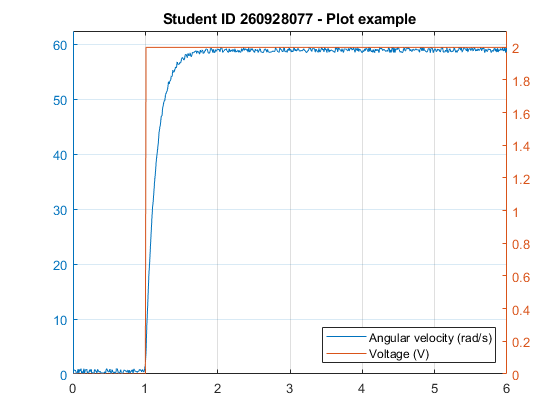

t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;

figure; clf;
yyaxis left
plot(t, w)
ylim([0, 1.05 * max(w)])
yyaxis right
plot(t, v)
ylim([0, 1.05 * max(v)])
xlim([0, startTime + duration])
legend('Angular velocity (rad/s)', 'Voltage (V)', ...
    'location', 'southeast');
title(sprintf('Student ID %s - Plot example', Students.ID));
grid on

## *2.3. Saving data*

The data generated by the motor can be saved using `Motor.save(...)`. The `save(...)` function takes two arguments: the `Students` structure (that is filled in the beginning of the lab), and a tag to identify data.

For example, to save the data from the last experiment with the tag 'Lab03_example', use:

Motor.save(Students, 'Lab03_example');

The data is saved in a `MAT`-file. In most hardware labs, you will be required to submit the `MAT` file along with the final LiveScript and the PDF report.

## *2.4. Loading data*

The `Motor.load(...)` function loads the data saved in the `MAT`-file. This is useful if your work is lost or corrupted. You can simply load the saved data rather than repeating the experiment. The `load` function takes 1 argument which is the tag of the data.

For example, we can load and plot the previously saved data by:

Motor.load('Lab03_example');

VirtualMotor::load::info: Recovering data collected by students: [260928077] .



t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;

figure; clf;
yyaxis left
plot(t, w)
ylim([0, 1.05 * max(w)])
yyaxis right
plot(t, v)
ylim([0, 1.05 * max(v)])
xlim([0, startTime + duration])
legend('Angular velocity (rad/s)', 'Voltage (V)', ...
    'location', 'southeast');
title(sprintf('Student ID %s - Plot example', Students.ID));
grid on

## **3. Data Collection: Determining Step Response**

The purpose of this experiment is to obtain the step response of the Virtual DC Motor. For this we will send a fixed voltage signal $V_{in} = 6$ volts and measure the angular velocity $\Omega$.

However, because of static friction, the transfer function between voltage and angular velocity is non linear at small voltages. To avoid this problem, we will apply a constant reference voltage of $V_{ref} = 4$ volts, before collecting the step input response.

## *Question 1 (2 marks)*

Complete the code below to apply a reference voltage of 4V for 5 seconds followed by an additional voltage of 6V for 5 seconds.

Vref = 4 % Reference signal

Vref = 4

Tref = 5 % Duration of reference signal

Tref = 5

Vin = 6 % Input signal

Vin = 6

Tin = 5 % Duration of input signal

Tin = 5


%Reset the motor power and timer
Motor.reset();

% Wait for the starting time (4V for 5s)
Motor.wait(Tref);
Motor.input(Vref);

% Drive the Motor (6V for 5s)
Motor.wait(Tin);
Motor.input(Vin);

% Stop the motor
Motor.off();

Motor.save(Students, 'Lab03.Q1');

## *Question 2 (1 mark)*

Complete the code below to plot your data

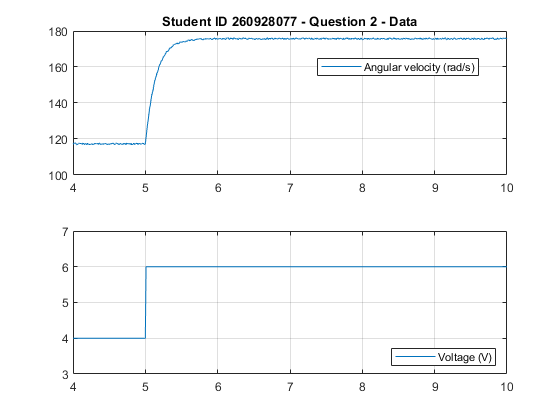

t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;


figure; clf;
subplot(2, 1, 1);
% [Answer here] plot angular velocity (w) vs time (t)
plot(t, w)
ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend('Angular velocity (rad/s)', 'location', 'best');
title(sprintf('Student ID %s - Question 2 - Data', Students.ID));
grid on
subplot(2, 1, 2)
% [Answer here] plot voltage (v) vs time (t)
plot(t, v)
ylim([3, 7])
xlim([Tref - 1, Tref + Tin])
legend('Voltage (V)', 'location', 'southeast');
grid on

## **2. System identification**

## *2.1. Data analysis*

In this section, we will use the step response obtained in `Question 2` to deduce the DC gain $K$ and the time constant $\tau$. Note that the values shown in a figure can be read by opening the figure and hovering the mouse at top of the line plot.

Observe that the measurement of the angular velocity is noisy. The noise can be reduced by taking the approximate average value rather than the exact value.

For example, we can get a better approximation of the reference angular velocity $\Omega_{ref}$ resulting from $V_{ref}$ by doing:

Wref = mean(w(t > Tref-1 & t < Tref)); % Compute the average value of "w" for "t" between "Tref - 1" and "Tref".

## *Question 3 (3 marks)*

From the plot in `Question 2` find the values of DC gain $K$ and time constant $\tau$.

% Computer the average value of "w" for t between 9 and 10 
finalValue = mean(w(t > Tref+Tin-1 & t < Tref+Tin));

K = (finalValue - w(t == Tref))/(Vin-Vref)

K = 29.1576


% We have to find the corresponding time value (x-axis value) corresponding to the
% following w (y-axis value):
w_corresponding_to_tau = (finalValue- w(t == Tref))*(1- exp(-1)) + w(t == Tref);

% Find the corresponding time (x-axis) value to the above w value (y-axis).
% This is done with 1D interpolation 
tau = interp1(w, t, w_corresponding_to_tau) - Tref

tau = 0.1450

## *2.2. Validating identified system*

We can use `MATLAB` to validate the calculated values of the DC gain and time constant. For this we will simulate a first order system with those values and compare it to the experimental results.

## *Question 4 (1 mark)*

Define a first order transfer function with the DC gain and time constant that you have obtained (use `tf` or `zpk`)

s = tf('s');

H = (K/(tau*s+1))

H =
 
     29.16
  -----------
  0.145 s + 1
 
Continuous-time transfer function.



The following code simulates the transfer function H(s) with a 2 volts input starting at $T_{ref}$. We are using `MATLAB` function `lsim` to simulate the output of a linear system with a given input.

tSim = t(t >= Tref & t < Tref+Tin) - Tref; % create a time signal from Tref to Tref + Tin
vSim = (Vin - Vref) * ones(size(tSim)); % create a constant voltage of Vin-Vref = 2 volts
vSim(1) = 0; % the initial state of the system is zero
wSim = Wref + lsim(H, vSim, tSim); % simulate the output of the system H

The following code shows the simulation and the experimental results on the same plot.

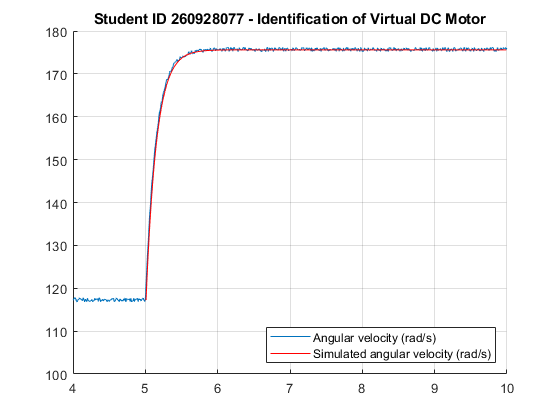

figure; clf;
hold on
plot(t, w) % experimental results
plot(tSim+Tref, wSim, 'r') % simulation of the identified transfer function
ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend('Angular velocity (rad/s)', ...
    'Simulated angular velocity (rad/s)', ...
    'location', 'southeast');
title(sprintf('Student ID %s - Identification of Virtual DC Motor', Students.ID));
grid on

We can measure the goodness of fit of the transfer function prediction by computing the Root-mean-square error (RMSE) between the experimental data and the predicted angular velocity with the model.


$$ RMSE = \sqrt{\displaystyle \frac{\sum_{i=1}^{n}(\omega_{Sim}(i) -
\omega_{Exp}(i))^2}{n}} $$


where $n$ is the number of elements in the angular velocity signal.

## *Question 5 (2 marks)*

- Complete the code to compute the RMSE of your fit

wExp = w(t >= Tref & t < Tref+Tin); % get the values of w between Tref and Tref + Tin

RMSE

- Can you tweak the values of the DC gain $K$ and time constant $\tau$ to get a better fit of the experimental data? Complete the following code to change the values of $K_{new}$ and $\tau_{new}$, re-define the transfer function $H_{new}$, re-simulate the new angular velocity, re-calculate the new RMSE, and re-plot the new fit.

KNew
tauNew
HNew

wSimNew

RMSENew


figure; clf;
hold on
plot(t, w) % experimental results
plot(tSim+Tref, wSim, 'r') % simulation of the identified transfer function
ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend('Angular velocity (rad/s)', ...
    'Simulated angular velocity (rad/s)', ...
    'location', 'southeast');
title(sprintf('Student ID %s - Question 5 - New RMSE = %4.2f', Students.ID, RMSENew));
grid on

## *Question 6 (1 mark)*

Another way to write the transfer function of a DC motor is as follows: $$ H(s) = \displaystyle \frac{K_t}{J R s + b R + K_t K_e} $$

Where

- $K_t$ is the torque proportionality constant in (Kg $m^2$/ $s^2$/A) or (N m/A)

- $K_e$ is the back electromotive proportionality constant in (V/rad/s)

- $R$ is the terminal resistance (Ohm)

- $J$ is the motor inertia (kg $m^2$)

- $b$ is the motor viscous friction constant in (Kg $m^2$/s) or (N m s)

Suppose we know that

Kt = 0.034;
Ke = 0.034;
R = 8.4;

Using the information obtained earlier, calculate the Motor viscous friction constant $b$.

b